Signál `harmonic_signal.m `je tvořen součtem několika harmonických složek. Signál je vzorkován s frekvencí fs=1000 Hz. Stejnosměrná složka všech harmonických složek signálu je nulová. 

Vaším úkolem je signál analyzovat a odpovědět na následující otázky v Moodle:

- Jaká je délka signálu v čase? (uveďte v sekundách)

- Jaká je celková energie signálu v časové doméně? (zaokrouhlete na celé číslo)

- Součtem kolika harmonických složek je signál tvořen?

- Jaká je frekvence harmonické složky signálu, která má nejvyšší amplitudu? (uveďte v Hz)

- Jaká je velikost (magnituda) spektrální čáry v amplitudovém spektru signálu, která odpovídá harmonické složce s nejvyšší amplitudou?

**Než začnete programovat, zkontolujte si, že analyzujete správný signál!**

**Odpovědi na otázky vyplňte do testu v Moodle. Po dokončení testu odevzdejte své skripty s řešením testových úloh do Moodle do záložky Programovací test.**

y = load('harmonic_signal.mat');   % upravte nazev souboru dle sve varianty!
y = y.y;
fs = 1000;
N = length(y);
T = length(y)/fs;
disp(T)

     5



Y = 1/N*fft(y);
t = linspace(0,(N-1)/fs,N);
f = linspace(0,fs -fs/N,N);

f =                          0                       0.2                       0.4                       0.6                       0.8                         1                       1.2                       1.4                       1.6                       1.8                         2                       2.2                       2.4                       2.6                       2.8                         3                       3.2                       3.4                       3.6                       3.8                         4                       4.2                       4.4                       4.6                       4.8                         5                       5.2                       5.4                       5.6                       5.8                         6                       6.2                       6.4                       6.6                       6.8                         7                       7.2                       7.4        

format long g
E = sum(abs(y).^2)

E =           7224.99999999988


idx = abs(Y)>0.5

idx = 1×5000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


disp(f(idx))

   168   832



disp(abs(Y(idx)))

         0.749999999999991         0.749999999999991



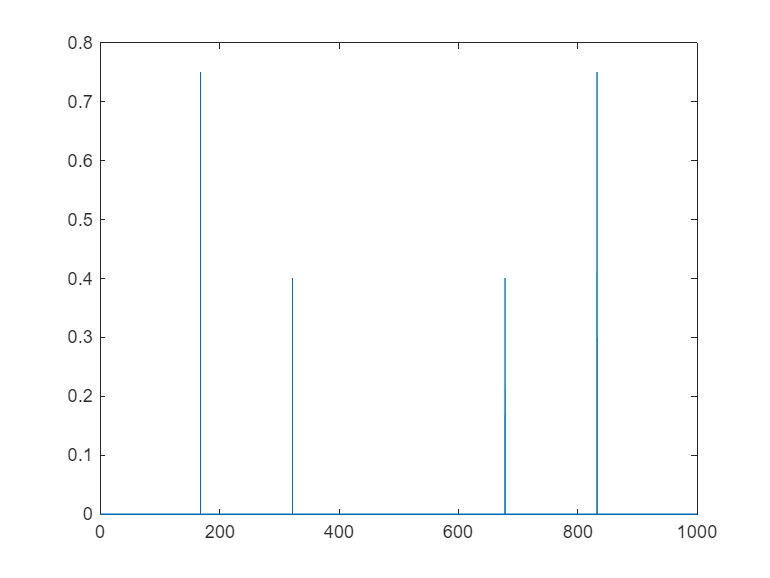

figure 
plot(f,abs(Y))